omega_p = 1.5708

omega_p = 1.5708

omega_s = 1.7203

omega_s = 1.7203

Delta_p = 0.05

Delta_p = 0.0500

Delta_s = 0.05

Delta_s = 0.0500


M_val = 50:1:70;
beta_val = 1.5:0.01:1.7;
Delta_val = 0.05;

ord = 100;
oc = 0;
b = 0;
opr = omega_p;
osr = omega_s;
dp = Delta_val(1);
ds = Delta_val(1);
omega_pr = 1.5739;
omega_sr = 1.7185;
best_p = Delta_val(1);
best_s = Delta_val(1);

for m = 1:2
    omega_p = omega_pr;
    omega_s = omega_sr;
    omega_c_val = linspace(omega_p, omega_s, 100);
    for n = 1:length(Delta_val)
        Delta_p = Delta_val(n);
        Delta_s = Delta_val(n);
        for i = 1:length(M_val)
            for j = 1:length(omega_c_val)
                for k = 1:length(beta_val)
                    M = M_val(i);
                    omega_c = omega_c_val(j);
                    beta = beta_val(k);
                    win = kaiser(M,beta);
                        
                    h = fir1(M-1, omega_c / pi, win);
    
                    [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s);
                    [omega_pr, omega_sr] = omega_r(h, Delta_p, Delta_s);
            
                    if Delta_pr <= best_p && Delta_sr <= best_s && M <= ord && omega_p >= 1.5708 && omega_s <= 1.7203 && Delta_p <= dp && Delta_s <= ds
                        best_filter = h;
                        best_p = Delta_pr;
                        best_s = Delta_sr;
                        ord = M;
                        oc = omega_c;
                        b = beta;
                        opr = omega_p;
                        osr = omega_s;
                        dp = Delta_p;
                        ds = Delta_s;
                    end
                end
            end
        end
    end
end

disp(['M = ' num2str(ord) ', omega_c = ' num2str(oc) ...
', Delta_p = ' num2str(dp) ', Delta_s = ' num2str(ds) ...
', Delta_pr = ' num2str(best_p) ', Delta_sr = ' num2str(best_s) ', beta = ' num2str(b) ...
', omega_pr = ' num2str(opr) ', omega_sr = ' num2str(osr)]);

M = 55, omega_c = 1.6469, Delta_p = 0.05, Delta_s = 0.05, Delta_pr = 0.046176, Delta_sr = 0.048742, beta = 1.62, omega_pr = 1.5739, omega_sr = 1.7185


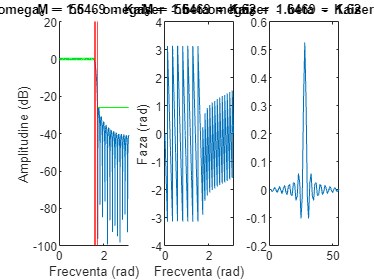


[H,w] = freqz(best_filter,1,5000);

h = best_filter;
omega_p = opr;
omega_s = osr;
omega_c = oc;
Delta_p = dp;
Delta_s = ds;

tp = linspace(0,opr,5000);
ts = linspace(osr,pi,5000);
xpp = mag2db(1+dp)*ones(size(tp));
xpm = mag2db(1-dp)*ones(size(tp));
xs = mag2db(ds)*ones(size(ts));

%Figura 20
figure;
subplot(1,3,1);
hold on;
plot(w,mag2db(abs(H)));
xline([opr oc osr], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("M = 55 - omega_c = 1.6469 - Kaiser - beta = 1.62");
hold off;

subplot(1,3,2);
plot(w,angle(H));
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("M = 55 - omega_c = 1.6469 - Kaiser - beta = 1.62");

subplot(1,3,3);
plot(best_filter);
title("M = 55 - omega_c = 1.6469 - Kaiser - beta = 1.62");

function [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s)
    [H, omega] = freqz(h, 1, 1000);

    omega_p_idx = find(omega <= omega_p);
    omega_s_idx = find(omega >= omega_s);

    H_p = abs(H(omega_p_idx));
    H_s = abs(H(omega_s_idx));

    Delta_pr = max(abs(1-H_p));
    Delta_sr = max(H_s);
end

function [omega_pr, omega_sr] = omega_r(h, Delta_p, Delta_s)
    [H, omega] = freqz(h, 1, 1000);

    K_p = find(abs(H) >= (1 - Delta_p), 1, 'last');
    K_s = find(abs(H) <= Delta_s, 1, 'first');
    
    omega_pr = omega(K_p);
    omega_sr = omega(K_s);
end
